close all; clear all;
if ~isfile('PhysionetData.mat')
    ReadPhysionetData        
end
load PhysionetData

set signal

Signals(1:5);
Labels(1:5);
summary(Labels);

     A       738 
     N      5050 


HIstogram

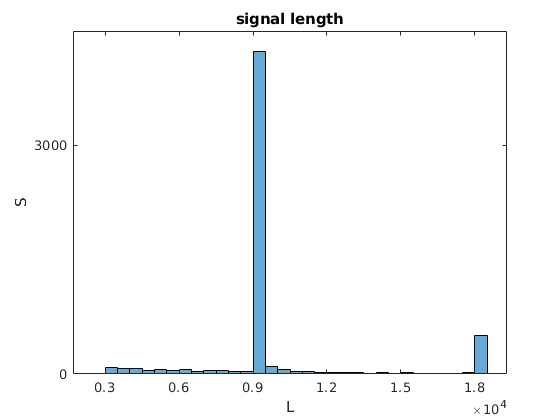

length = cellfun(@length,Signals);
h = histogram(length);
xticks(0:3000:18000);
yticks (0:3000:18000);
title('signal length')
xlabel('Length')
ylabel('S')

Segmentation

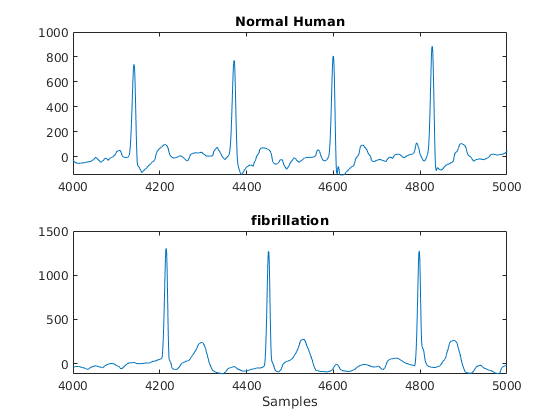

fibrilltion = Signals{4};
normal = Signals{1};

figure (1)
subplot(2,1,1)
plot(normal)
title("Normal Human")
xlim([4000,5000])

subplot(2,1,2)
plot(fibrilltion)
title('fibrillation')
xlim([4000,5000])
xlabel('Samples')

prepare for training

[Signals,Labels] = segmentSignals(Signals,Labels);

Train using raw data

%summary(Labels);
Signals(1:5);

splitting

sickX = Signals(Labels=='A');
sickY = Labels(Labels=='A');

normalX = Signals(Labels=='N');
normalY = Labels(Labels=='N');

divide random

[trainIndA,~,testIndA] = dividerand(718,0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(4937,0.9,0.0,0.1);

XTrainA = sickX(trainIndA);
YTrainA = sickY(trainIndA);
XTrainN = normalX(trainIndN);
YTrainN = normalY(trainIndN);

XTestA = sickX(testIndA);
YTestA = sickY(testIndA);

XTestN = normalX(testIndN);
YTestN = normalY(testIndN);

case all of them have the same label

XTrain = [repmat(XTrainA(1:634),7,1); XTrainN(1:4438)];
YTrain = [repmat(YTrainA(1:634),7,1); YTrainN(1:4438)];
XTest = [repmat(XTestA(1:70),7,1); XTestN(1:490)];
YTest = [repmat(YTestA(1:70),7,1); YTestN(1:490);];

Summary

summary(YTrain)

     A      4438 
     N      4438 


Network

layers = [
sequenceInputLayer(1)
bilstmLayer(100,'OutputMode',"last")
fullyConnectedLayer(2)
softmaxLayer
classificationLayer

]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   BiLSTM                  BiLSTM with 100 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

options

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'SequenceLength', 1000, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

TRAIN

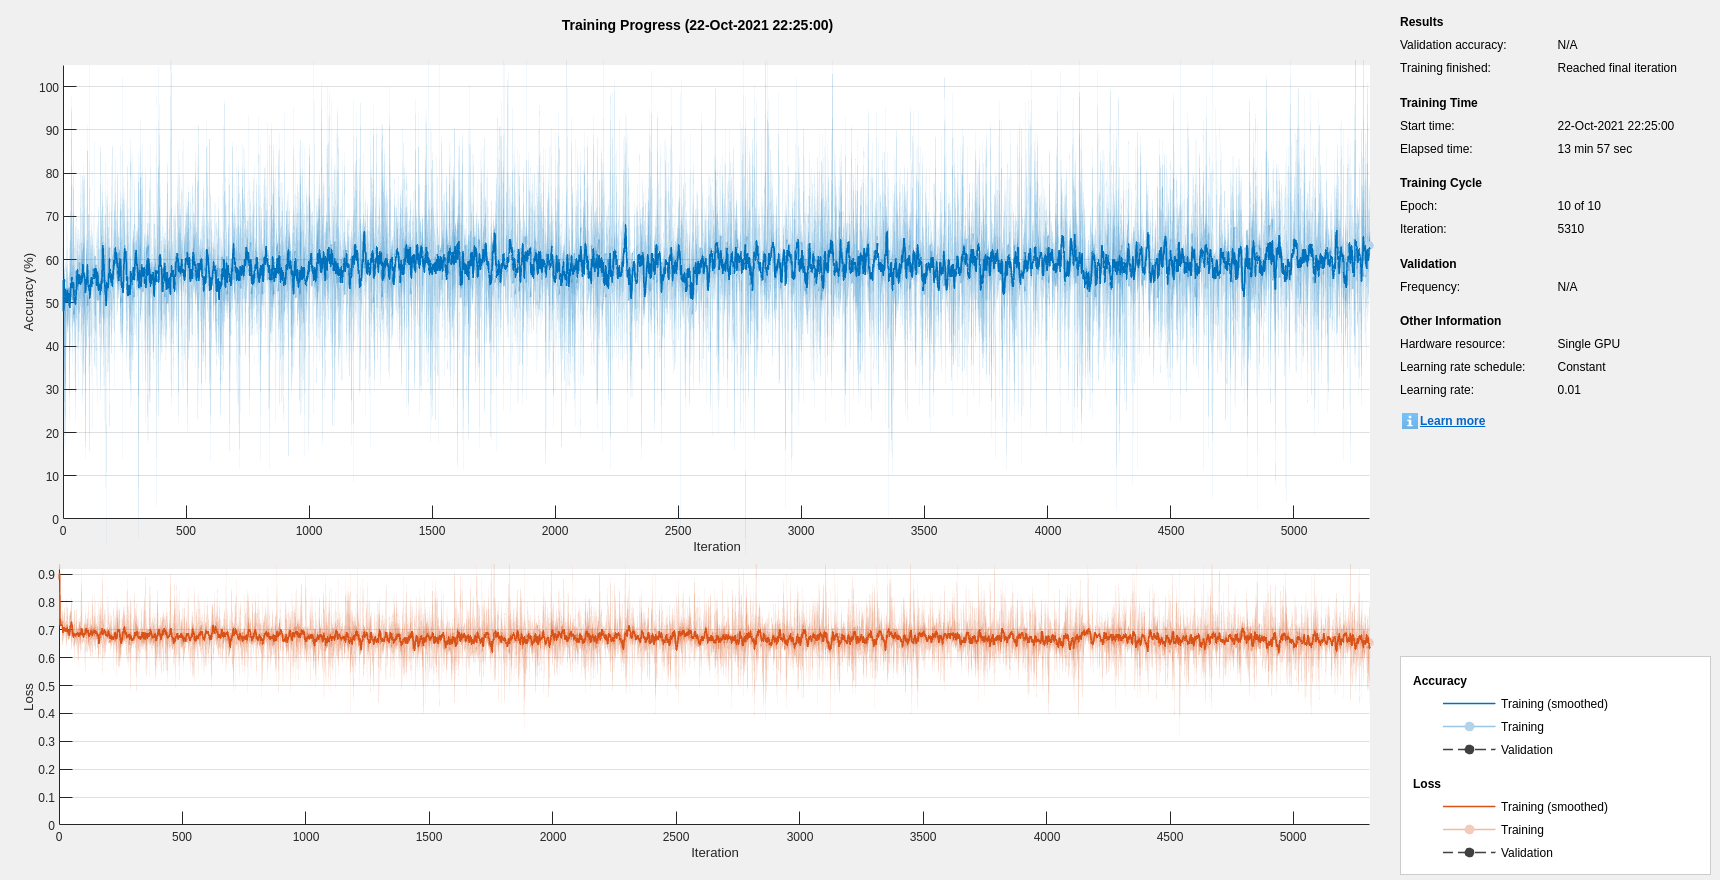

net =   SeriesNetwork with properties:

         Layers: [5×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


net = trainNetwork(XTrain,YTrain,layers,options)